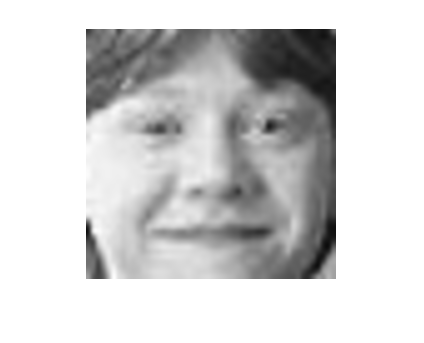

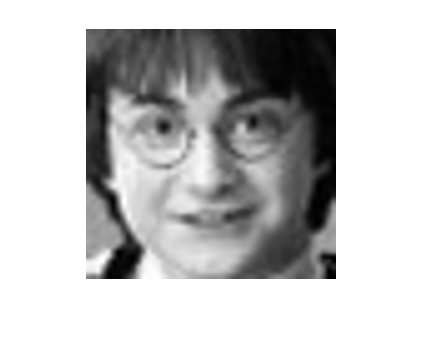

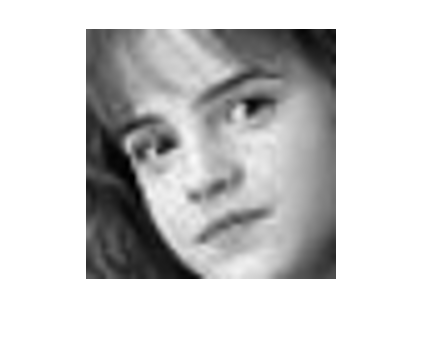

I=imread('HP.jpg');
X = extractFaces(I,50);
%displaying detected faces
displayFaces(X,50,5);

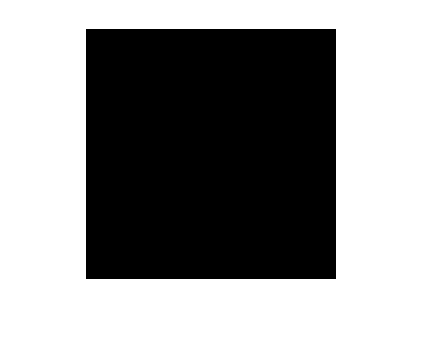

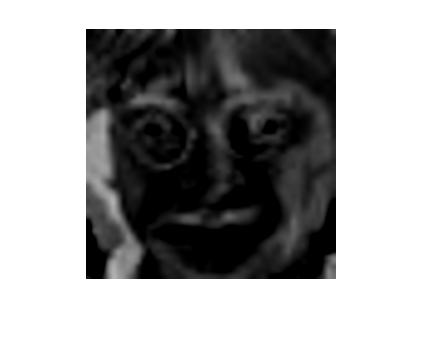

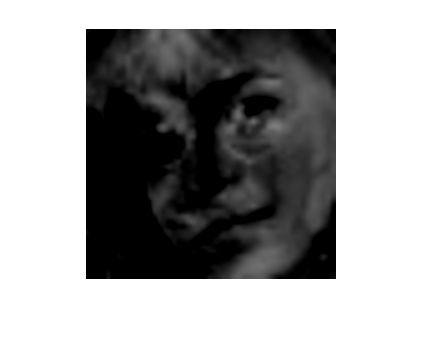


%traning system on input faces
[X_norm,mu,~] = featureNormalize(X);
[eigVec, eigVal] = pca(X_norm);
[Y,omega] = generateEiganFaces(X_norm,eigVec);

%displaying eigan faces
displayFaces(Y,50,5);

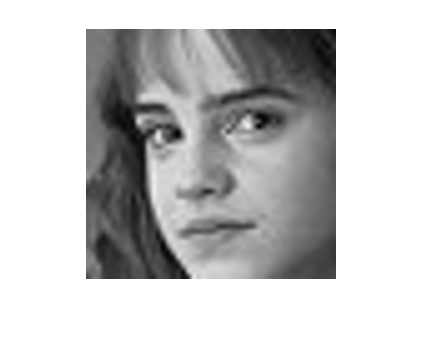

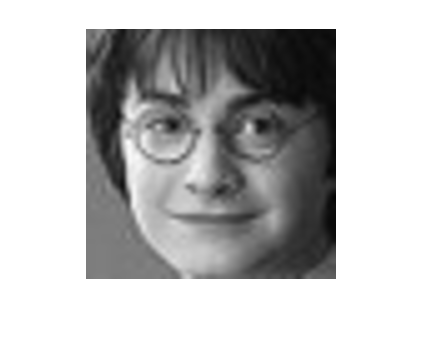

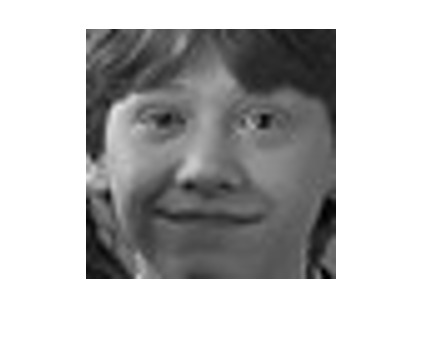

csvwrite("eiganFaces.csv",Y);

% test faces
A = imread("HP2.jpg");
A = extractFaces(A,50);
%displaying test faces
displayFaces(A,50,5);


%testing second test face
displayFaces(A(:,2),50,5);

index = testFace(Y,A(:,2),mu,omega);

%if match found
if(index ~= 0)
    displayFaces(X(:,index),50,5);

end